# ARI - Homework 7		

% initialize
clear all
close all
clc

% useful commands
help tf 

 tf  Construct transfer function or convert to transfer function.
 
   Construction:
     SYS = tf(NUM,DEN) creates a continuous-time transfer function SYS with
     numerator NUM and denominator DEN. SYS is an object of type tf when
     NUM,DEN are numeric arrays, of type GENSS when NUM,DEN depend on tunable
     parameters (see REALP and GENMAT), and of type USS when NUM,DEN are
     uncertain (requires Robust Control Toolbox).
 
     SYS = tf(NUM,DEN,TS) creates a discrete-time transfer function with
     sample time TS (set TS=-1 if the sample time is undetermined).
 
     S = tf('s') specifies the transfer function H(s) = s (Laplace variable).
     Z = tf('z',TS) specifies H(z) = z with sample time TS.
     You can then specify transfer functions directly as expressions in S
     or Z, for example,
        s = tf('s');  H = exp(-s)*(s+1)/(s^2+3*s+1)
 
     SYS = tf

help feedback

 feedback  Feedback connection of two input/output systems. 
 
    M = feedback(M1,M2) computes a closed-loop model M for the feedback loop: 
 
           u --->O---->[ M1 ]----+---> y
                 |               |           y = M * u
                 +-----[ M2 ]<---+
 
    Negative feedback is assumed and the model M maps u to y. To apply 
    positive feedback, use the syntax M = feedback(M1,M2,+1).
 
    M = feedback(M1,M2,FEEDIN,FEEDOUT,SIGN) builds the more general feedback 
    interconnection:
 
                       +------+
           v --------->|      |--------> z
                       |  M1  |
           u --->O---->|      |----+---> y
                 |     +------+    |
                 |                 |
                 +-----[  M2  ]<---+
 
    The vector FEEDIN contains indices into the input vector of M1 and
    specifies which inputs u are involved in the feedback loop. Similarly, 
    FEED

help sisotool

 sisotool  SISO Design Tool.
 
    sisotool opens the SISO Design Tool.  This Graphical User Interface
    lets you design single-input/single-output (SISO) compensators by
    graphically interacting with the root locus, Bode, and Nichols plots of
    the open-loop system.  To import the plant data into the SISO Tool,
    select the Import item from the File menu. By default, the control
    system configuration is
 
              r -->[ F ]-->O--->[ C ]--->[ G ]----+---> y
                         - |                      |
                           +-------[ H ]----------+
 
    where C and F are tunable compensators.
 
    sisotool(G) specifies the plant model G to be used in the SISO Tool.
    Here G is any linear model created with TF, ZPK, or SS.
 
    sisotool(G,C) and sisotool(G,C,H,F) further specify values for the
    feedback compensator C, sensor H, and prefilter F.  By default,
    C, H,

help step

 step  Step response of dynamic systems.
 
    [Y,T] = step(SYS) computes the step response Y of the dynamic system SYS. 
    The time vector T is expressed in the time units of SYS and the time 
    step and final time are chosen automatically. For multi-input systems,
    independent step commands are applied to each input channel. If SYS has 
    NY outputs and NU inputs, Y is an array of size [LENGTH(T) NY NU] where 
    Y(:,:,j) contains the step response of the j-th input channel.
 
    For state-space models, 
       [Y,T,X] = step(SYS) 
    also returns the state trajectory X, an array of size [LENGTH(T) NX NU] 
    for a system with NX states and NU inputs.
 
    For identified models (see IDMODEL),
       [Y,T,X,YSD] = step(SYS) 
    also computes the standard deviation YSD of the response Y (YSD is empty 
    if SYS does not contain parameter covariance information).
 
    [Y,...] = step(SYS

help bode

 bode  Bode frequency response of dynamic systems.
 
    bode(SYS) draws the Bode plot of the dynamic system SYS. The frequency 
    range and number of points are chosen automatically.
 
    bode(SYS,{WMIN,WMAX}) draws the Bode plot for frequencies between WMIN 
    and WMAX in radians/TimeUnit (relative to the time units specified in 
    SYS.TimeUnit, the default being seconds).
 
    bode(SYS,W) uses the vector W of frequencies (in radians/TimeUnit) to
    evaluate the frequency response. See LOGSPACE to generate logarithmically 
    spaced frequency vectors.
 
    bode(SYS1,SYS2,...,W) graphs the Bode response of several systems
    SYS1,SYS2,... on a single plot. The frequency vector W is optional. 
    You can specify a color, line style, and marker for each model, for
    example:
       bode(sys1,'r',sys2,'y--',sys3,'gx').
 
    [MAG,PHASE] = bode(SYS,W) and [MAG,PHASE,W] = <s

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




% type 'help' followed by the command to learn about that specific function
% using the percent sign allows comments in MATLAB
% to compile/run your livescript hit "run" at the top of your screen
os = 20;
l = log(os/100);
e = (-l/sqrt(pi^2 + l^2));
PM = -180 + atan(2*e/(-2*e + sqrt(1 +4*e^2)))*180/pi

PM = -115.8317

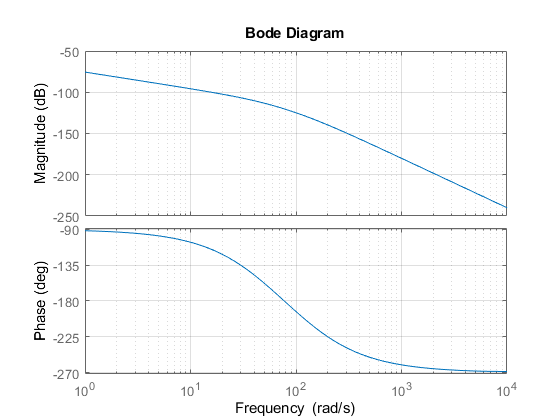

L = 1/(s*(s+50)*(s+120));
bode(L)
hold on
grid on
hold off

K = 10^5;
L = L*K

L =
 
          100000
  ----------------------
  s^3 + 170 s^2 + 6000 s
 
Continuous-time transfer function.



M = feedback(L, 1)

M =
 
              100000
  -------------------------------
  s^3 + 170 s^2 + 6000 s + 100000
 
Continuous-time transfer function.



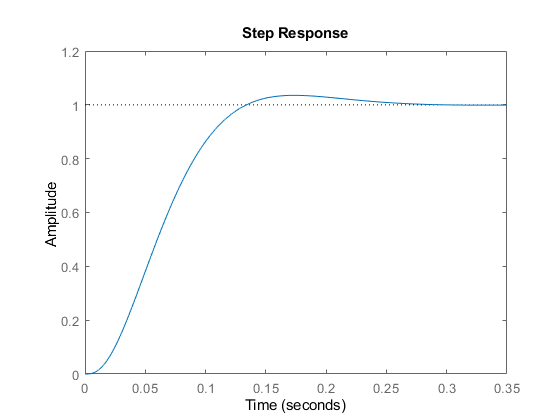

step(M)

## Tasks 	

*Please answer the following in the spaces provided below, justify your conclustion:	*

#### Assignment 1 – Design of the controller gain on the prescribed overshoot							

The transfer function of the open-loop is:


$$L\left(s\right)=\frac{K}{s\left(s+50\right)\left(s+120\right)}$$
		

- Use the frequency methods for the design of the gain $K$such that the overshoot of the closed-loop system during the step response is 20%. 		

- Run numerical simulation to verify your result.

#### Assignment 2 – Characteristics of the steady-state from the Bode plot							

On the following figure are frequency characteristics of three different systems $\left|L\left(j\omega \right)\right|$, a), b), and c). Use your date of birth. If you were born in the first third of the month use a), if you were born in the second third of the month use b) and if you were born in the last third of the month use c). Solve the following tasks:

- Determine the type of the system that means the order of the astatism. 

- Determine the constants of the steady-state $K_p =\lim_{s\to 0} \;L\left(s\right)$,$\;K_v =\lim_{s\to 0} \;sL\left(s\right)$, and $K_a =\underset{s\to 0}{\lim \;} s^2 L\left(s\right)$

- Determine the steady-state error on the step, ramp and parabola of the reference input.